# MDP Formulation for canonical example

An MDP is both a representation of a problem, and the solution to the problem, so for someone unfamiliar with the terminology, implementation, or various steps required to derive both the representation and solution, it can be confusing. The representation part of the MDP consists of three things:

- States

- Actions

- Transition matrix

### Visualize the grid world

% f1 = visualizeGridWorld(1, map, poi, state, agent, policy);
% title("Tabletop Grid World");

## MDP Formulation for canonical example

An MDP is both a representation of a problem, and the solution to the problem, so for someone unfamiliar with the terminology, implementation, or various steps required to derive both the representation and solution, it can be confusing. The representation part of the MDP consists of three things:

- States

- Actions

- Transition matrix

### set of actions

This is a list of all possible actions regardless of the state or constraints. Upon initialization, each state is assigned all actions as valid actions, and then in a subsequent step, the valid actions are obtained by parsing a list of constraints.

actions = ['^', 'v', '<', '>'];

### set of states

a representation I like is to use is csv strings [mixed data type arrays or lists are good too], where the index maps to a feature and is updated in code when the feature variables value updates. Once you have your state prototype, and you know the set of possible values each feature variable can hold, it is a simple combinatorial function to generate the state space. States have rewards and values, but more on that below. Here, the set of states are just the locations on a grid, and includes unreachable states, such as blocks. These unreachable states are dealt with when building the transition matrix.

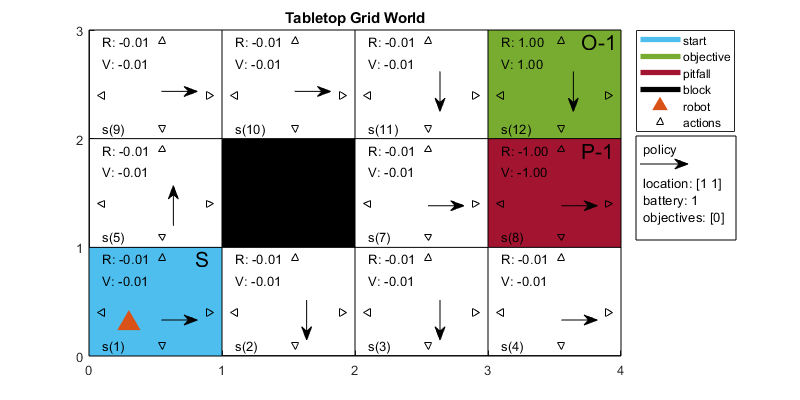

% grid size
width = 4;
height = 3;


% start location 
start = [1,1];

% location prototype
location.type = "normal"; 
location.label = "";
location.reward = 0.2;
location.value = location.reward;
location.validActions = actions;

% map is a matrix of structs
map = repmat(location, width, height);

% poi are map features 
poi.start = start;
poi.objectives = [4,3];% [8,5; 2,6];
poi.pitfalls = [4,2];%[2,5; 4,1; 6,2; 8,2; 6,6; 6,7; 7,7];
poi.blocks = [2,2];%[1,4; 4,3; 6,3; 5,3; 2,2; 5,4; 5,5];
map(poi.start(1), poi.start(2)).type = "start";
for i=1:length(poi.objectives(:,1))
    map(poi.objectives(i,1), poi.objectives(i,2)).type = "objective";
    map(poi.objectives(i,1), poi.objectives(i,2)).label = sprintf("O-%d", i);
    map(poi.objectives(i,1), poi.objectives(i,2)).reward = 1.0;
    map(poi.objectives(i,1), poi.objectives(i,2)).value = 1.0;
end
for i=1:length(poi.pitfalls(:,1))
    map(poi.pitfalls(i,1), poi.pitfalls(i,2)).type = "pitfall";
    map(poi.pitfalls(i,1), poi.pitfalls(i,2)).label = sprintf("P-%d", i);
    map(poi.pitfalls(i,1), poi.pitfalls(i,2)).reward = -1.0;
    map(poi.pitfalls(i,1), poi.pitfalls(i,2)).value = -1.0;
end
for i=1:length(poi.blocks(:,1))
    map(poi.blocks(i,1), poi.blocks(i,2)).type = "block";
    map(poi.blocks(i,1), poi.blocks(i,2)).reward = 0.0;
    map(poi.blocks(i,1), poi.blocks(i,2)).value = 0.0;
end

% a wrapper variable 
states = 1:1:length(map(:));

% for plotting only currently
% [WIP] will update code to incorporate 
agent.type = "robot";
agent.location = start;
agent.distance = 0;
agent.direction = '^';
agent.soc = 100;
agent.locationType = location.type;
agent.cumulativeReward = int16(0);
state.location = agent.location;
state.battery = 1;
state.achieved1 = false;

### transition matrix

This information stores `P(s`|s,a)`, the probability of transitioning into state` s`` from state` s `taking action` a`, for all `s` and` a`. this matrix is of dimensions (*|S| x |S| x |A|*), where `P(S=s(k)|S=s(j),A=a(n)), 1 <= k,j <= |S|, 1 <= n <= |A|, is found in the transition matrix T, at T(k,j,n). `This matrix must be built from domain knowledge or information supplied (such as from component data sheets, past observations, etc...). If this information is not supplied, then it can be approximated with a series of observed state transitions.

- assume actions have the same probability in all states

- p(success) = .8, p(fail_left) = .1, p(fail_right) = .1

- if an action leads to an unreachable state, then the agent stays put

p_success = .8;
p_fail_left = .1;
p_fail_right = .1;

% initialize the transition matrix
% T(s'|s,a) s' = first idx, s = second idx, a = third idx
% first entry says, the probability of transitioning to state 1, from state
% 1, going up, is .1. 
T(1,1,1) = 0;

% this is the numel(map) state number, just another method access the state
num = 1;
% equivalent to (after i and j are initialized)
% num = i*width - (width-j);

% iterate the y coordinate
for i=1:height
    % iterate the x coordinate
    for j=1:width
        % map(x,y) 
        map(j,i).validActions = getValidActions(j,i, map, actions);
        %k = i*width - (width-j);
        % for each valid action
        for n = 1:length(map(j,i).validActions)
            % get the current action
            action = map(j,i).validActions(n);
            % select by action type
            if(action == '^')
                % probability of action success
                T(num+width, num, 1) = p_success;
                % probability of action failing to the left <
                if(num - 1 > 0)
                    % if left is a reachable state
                    T(num-1, num, 1) = p_fail_left;
                else 
                    % if not, then the agent stays put
                    T(num, num, 1) = p_fail_left;
                end
                % probabiliity of action failing to the right >
                if(num + 1 <= width)
                    % if right is a reachable state
                    T(num+1, num, 1) = p_fail_right;
                else
                    % if not, then the agent stays put
                    T(num, num, 1) = p_fail_right;
                end % comments repeat for other actions
            elseif(action == 'v')
                T(num-width, num, 2) = p_success;
                 % left
                if(num - 1 > 0)
                    T(num-1, num, 2) = p_fail_left;
                else 
                    T(num, num, 2) = p_fail_left;
                end
                % right
                if(num + 1 <= width)
                    T(num+1, num, 2) = p_fail_right;
                else
                    T(num, num, 2) = p_fail_right;
                end
                
            elseif(action == '<')
                T(num-1, num, 3) = p_success;
                % up
                if(i < height)
                    T(num+width, num, 3) = p_fail_right;
                else 
                    T(num, num, 3) = p_fail_right;
                end
                % down
                if(i > 1)
                    T(num-width, num, 3) = p_fail_left;
                else
                    T(num, num, 3) = p_fail_left;
                end
                
            elseif(action == '>')
                T(num+1, num, 4) = .8;
                % up
                if(i < height)
                    T(num+width, num, 4) = p_fail_left;
                else 
                    T(num, num, 4) = p_fail_left;
                end
                % down
                if(i > 1)
                    T(num-width, num, 4) = p_fail_right;
                else
                    T(num, num, 4) = p_fail_right;
                end
            else
                disp('invalid action.');
            end
        end
        num = num + 1;
    end
end
clear i;
clear j;

## Solving the MDP

### Reward

rewards = [map.reward]; % the rewards are held within each state in the map

### Value 

values = [map.value]; % values are held within each state in the map

### Value Iteration

### Optimal Policy

This information stores

% define a default policy as the random policy
policy = randi(length(actions), 1, numel(map));

%f2 = visualizeGridWorld(2, map, poi, state, agent, policy);
%title("Tabletop Grid World with random policy");

## Implementation

### Gamma

gamma is the discount factor, or the relative importance of the reward of the next step (the next-next step is gamma^2, next-next-next is gamma^3, ...)

gamma = .9;

### Beta

beta is the minimum amount of improvement need between iterations to continue the value iteration algorithm

beta = .005;

### Value Iteration

old_values = ones(1, length(rewards))*-999;
policy1 = repmat("", 1, length(states));
i = 1;
% disp(values);
while(abs(sum(values) - sum(old_values)) > beta)
    old_values = values;
    for j=1:length(states)
        vals = zeros(1, length(actions));
        for n=1:length(actions)
            for k=1:length(states)
                vals(n) = vals(n) + T(k,j,n)*values(k);
                % if j == 1 && n == 1
                %    debug(i,j,k,length(states), n, T(k,j,n), values(k));
                % end
            end
        end
        [m,idx] = max(vals);
        values(j) = rewards(j) + gamma * m;
        policy1(j) = actions(idx);
        if actions(idx) == '^'
            policy(j) = 1;
        elseif actions(idx) == 'v'
            policy(j) = 2;
        elseif actions(idx) == '<'
            policy(j) = 3;
        elseif actions(idx) == '>'
            policy(j) = 4;
        else
            disp('error shouldnt reach.');
        end
        map(j).value = values(j);
        map(j).policy = policy(j);
    end
    i = i + 1;
end
disp("stopping criteria met. State values have been permanently assigned.");
fprintf("Optimal Policy with gamma: %.2f\tbeta: %.3f\tpersistent reward: %.2f\n", gamma, beta, rewards(1));
for i = 1:length(states)
    fprintf("%c*(%d) = %s\n", 960, states(i), policy1(i));
end
f3 = visualizeGridWorld(3, map, poi, state, agent, policy);
title("Tabletop Grid World");

## MDP Formulation for 2 state example

% states could even be string encodings of multiple variables
states = ["s1", "s2"];

% actions, like states, can be anything
actions = ["a1", "a2"];

% the rewards of the states should encode the agents real-world objective(s)
rewards = [3, -1];

% initialize the states value aka utility to its reward
values = rewards(:)';

% the transition function must be manually encoded with probabilities provided in the 
% problem definition (or estimated given a sequence of states - more on that later)
% this is formulated as T(s'|s, a) where T(1,:,:) = s', T(:,1,:) = s ...
T(1,1,1) = 0;
T(1,1,2) = .5;
T(1,2,1) = 1.0;
T(1,2,2) = 0;
T(2,1,1) = 1.0;
T(2,1,2) = .5;
T(2,2,1) = 0;
T(2,2,2) = 1.0;

stopping criteria met. State values have been permanently assigned.


Optimal Policy with gamma: 0.90	beta: 0.005	persistent reward: 0.20


% gamma is the discount factor, or the relative importance of the reward of the 
% next step (the next-next step is gamma^2, next-next-next is gamma^3, ...)
gamma = .5;

π*(1) = ^
π*(2) = >
π*(3) = ^
π*(4) = <
π*(5) = ^
π*(6) = ^
π*(7) = ^
π*(8) = ^
π*(9) = >
π*(10) = >
π*(11) = >
π*(12) = <


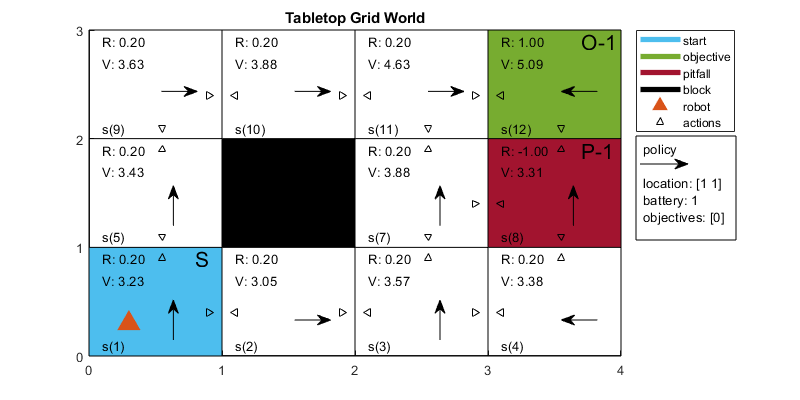


% beta is the minimum amount of improvement need between iterations to

% continue the value iteration algorithm
beta = .005;

### Value Iteration

old_values = ones(1, length(rewards))*-999;
stopping_criteria = .005;
actions2 = repmat("", 1, length(states));
i = 1;
disp(values);
while(abs(sum(values) - sum(old_values)) > beta)
    old_values = values;
    for j=1:length(states)
        vals = zeros(1, length(actions));
        for n=1:length(actions)
            for k=1:length(states)
                vals(n) = vals(n) + T(k,j,n)*values(k);
                if j == 1 && n == 1
                    debug(i,j,k,length(states), n, T(k,j,n), values(k));
                end
            end
        end
        [m,idx] = max(vals);
        
        values(j) = rewards(j) + gamma * m;
        actions2(j) = actions(idx);
        
    end
    i = i + 1;
end
disp("stopping criteria met. State values have been permanently assigned.");
for i = 1:length(states)
    fprintf("%c*(%s) = %s\n", 960, states(i), actions2(i));
end
disp(values);

### [optional] Move the robot, and revisualize

- The robot cannot travel off of the grid or on a black spot

agent = moveAgent(agent, '>', 1, map, poi);
state = update_state(state, agent, map);
f2 = visualizeGridWorld(2, map, poi, state, agent);

### [optional] Robot Teleop

- reads arrow keys, q to quit (press enter to close pop up figure)

- run above block to generate figure 2

teleop(agent, 2, map, poi, state);

## Shortest path test

G = convert2graph(map, "block", "pitfall");
start_ID = 1;
obj1_ID = 8;%40;

     3    -1



%obj2_ID = 58;

[P, d, edgepath] = shortestpath(G, start_ID, obj1_ID);
dirs = get_path_directions(map, P);

%reset agent and state 
state.location = agent.location;
state.battery = 1;
state.achieved1 = false;
state.achieved2 = false;

agent = set_agent(agent, map, [1,1], 0, '^', 100, 1, 0);
for i=1:length(dirs)
    f3 = visualizeGridWorld(3, map, poi, state, agent);
    if i < length(dirs)
        agent = moveAgent(agent, dirs(i), 1, map, poi);
        state = update_state(state, agent, map); %rename this function
    end
    pause(.3);
end

i: 1	j: 1	n: 1	T(k,j,n): 0.000	V(k): 3.000  + T(k,j,n): 1.000	V(k): -1.000
i: 2	j: 1	n: 1	T(k,j,n): 0.000	V(k): 3.500  + T(k,j,n): 1.000	V(k): 0.750
i: 3	j: 1	n: 1	T(k,j,n): 0.000	V(k): 4.063  + T(k,j,n): 1.000	V(k): 1.031
i: 4	j: 1	n: 1	T(k,j,n): 0.000	V(k): 4.273  + T(k,j,n): 1.000	V(k): 1.137
i: 5	j: 1	n: 1	T(k,j,n): 0.000	V(k): 4.353  + T(k,j,n): 1.000	V(k): 1.176
i: 6	j: 1	n: 1	T(k,j,n): 0.000	V(k): 4.382  + T(k,j,n): 1.000	V(k): 1.191
i: 7	j: 1	n: 1	T(k,j,n): 0.000	V(k): 4.393  + T(k,j,n): 1.000	V(k): 1.197
i: 8	j: 1	n: 1	T(k,j,n): 0.000	V(k): 4.397  + T(k,j,n): 1.000	V(k): 1.199


function debug(i, j, k, K, n, t, v)

stopping criteria met. State values have been permanently assigned.


    if(k == 1)
        fprintf("i: %.d\tj: %d\tn: %d\tT(k,j,n): %.3f\tV(k): %.3f ", i, j, n, t, v);
    else

π*(s1) = a2
π*(s2) = a1


        fprintf("T(k,j,n): %.3f\tV(k): %.3f", t, v);

    4.3991    1.1995



    end
    if(k ~= K)
        fprintf(" + ");
    else
        fprintf("\n");
    end
end